[num, den] = ss2tf(dc_motor_ss.A, dc_motor_ss.B, dc_motor_ss.C, dc_motor_ss.D);
H = tf(num, den)


H =
 
         6.667
  -------------------
  s^2 + 4.033 s + 0.8
 
Continuous-time transfer function.


p = pole(H)

p =    -3.8241
   -0.2092


(p(1) + p(2)) / 2

ans = -2.0167

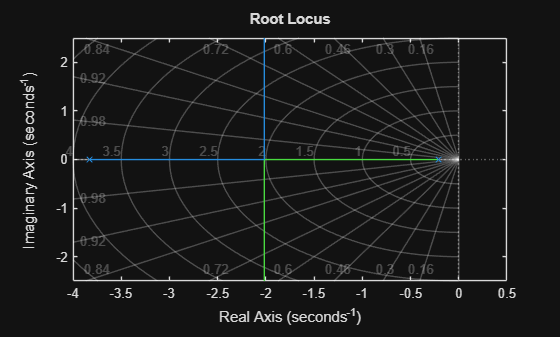

rlocus(H);
grid on;

T_s=1.9;
os=0.0215;

zeta = sqrt(log(os)^2 / (pi^2 + log(os)^2));
zeta

zeta = 0.7740

w_n = 4 / (T_s * zeta);
w_n

w_n = 2.7201

poles = zeros(2,1);
poles(1) = -w_n*zeta + 1i * w_n * sqrt(1-zeta^2);
poles(2) = -w_n*zeta - 1i * w_n * sqrt(1-zeta^2);
desired_pole = poles(1);
desired_pole

desired_pole = -2.1053 + 1.7225i

poles

poles =   -2.1053 + 1.7225i
  -2.1053 - 1.7225i


theta = angle(evalfr(H, poles(1))) * 180/pi;
theta

theta = 177.1935

dtheta = 180-theta

dtheta = 2.8065

z = 0.25;
zero_arg = angle(desired_pole + z) * 180/pi;
zero_arg

zero_arg = 137.1252

pole_arg = zero_arg - dtheta;
pole_arg

pole_arg = 134.3187

p = imag(desired_pole) / tan(pole_arg*pi/180) - real(desired_pole)

p = 0.4233

lead = tf([1, z], [1, p]);
lead


lead =
 
   s + 0.25
  ----------
  s + 0.4233
 
Continuous-time transfer function.


K = 1 / abs(evalfr(H, desired_pole) * evalfr(lead, desired_pole));
K

K = 0.8892

final_lead = K * lead;
final_lead


final_lead =
 
  0.8892 s + 0.2223
  -----------------
     s + 0.4233
 
Continuous-time transfer function.


K_gain = K * z / p;
K_gain 

K_gain = 0.5252

T_lead = 1 / z;
T_lead 

T_lead = 4

T_lag = 1 / p;
T_lag 

T_lag = 2.3627

T = feedback(final_lead * H,1);
lead_gain = dcgain(T)

lead_gain = 0.8140

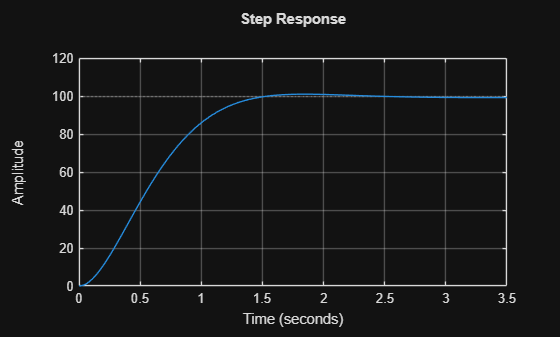

T = T / dcgain(T);
step(100*T);
grid on

stepinfo(100*T)

ans = struct with fields:
         RiseTime: 0.8995
    TransientTime: 1.3783
     SettlingTime: 1.3783
      SettlingMin: 90.1956
      SettlingMax: 100.9540
        Overshoot: 0.9540
       Undershoot: 0
             Peak: 100.9540
         PeakTime: 1.8375


pole(T)

ans =   -2.1053 + 1.7225i
  -2.1053 - 1.7225i
  -0.2461 + 0.0000i
